# Tipos de filtros y su respuesta en una señal de ECG

## Lectura de señal de ECG en formato .edf (European Data Format)

[Header,Friday] = edfread('05-Sarah_Goytortua_Viernes.edf');

Step 1 of 2: Reading requested records. (This may take a few minutes.)...
Step 2 of 2: Parsing data...


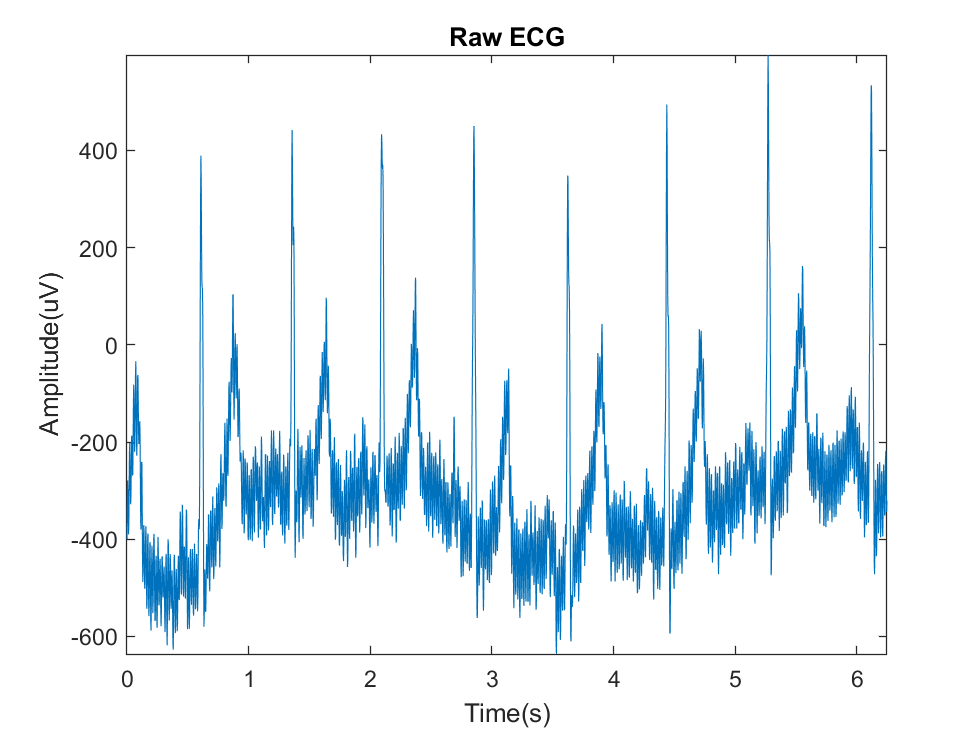

Friday = Friday(1:2500)*-1;
Fs = Header.frequency;                             %Frecuencia de muestreo contenida en el archivo    
N = length(Friday);                                %Longitud del vector                                                
T = (0:N-1)*1/Fs;                                  %Vector de tiempo  
plot(T,Friday);
    axis tight;
    title('Raw ECG');
    xlabel('Time(s)');
    ylabel('Amplitude(uV)');

## Primer filtro: Butterworth Pasa Altas

Elegimos un filtro pasa altas, que elimine las componentes parásitas de la señal. El coeficiente Wn de la función **butter** es la frecuencia normalizada, utilizada en filtros digitales, que representa la cantidad de ciclos/muestras.

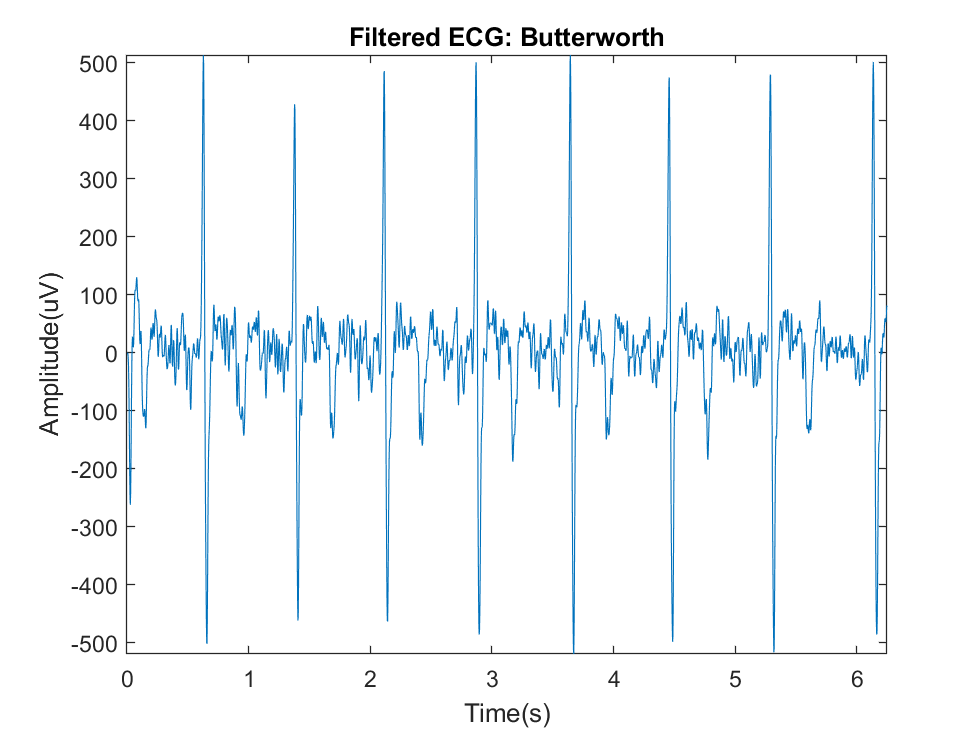

Fc = 5;
Wn = Fc/(Fs/2);                                %Frecuencia normalizada
[num,den] = butter(2,Wn,'high');
Butter_Friday = filter(num,den,Friday);

Fc = 50;
Wn = Fc/(Fs/2);                                
[num,den] = butter(10,Wn,'low');

Butter_Friday = filter(num,den,Butter_Friday);
plot(T,Butter_Friday);
    axis tight;
    title('Filtered ECG: Butterworth');
    xlabel('Time(s)');
    ylabel('Amplitude(uV)');

## Segundo filtro: Chebyshev II

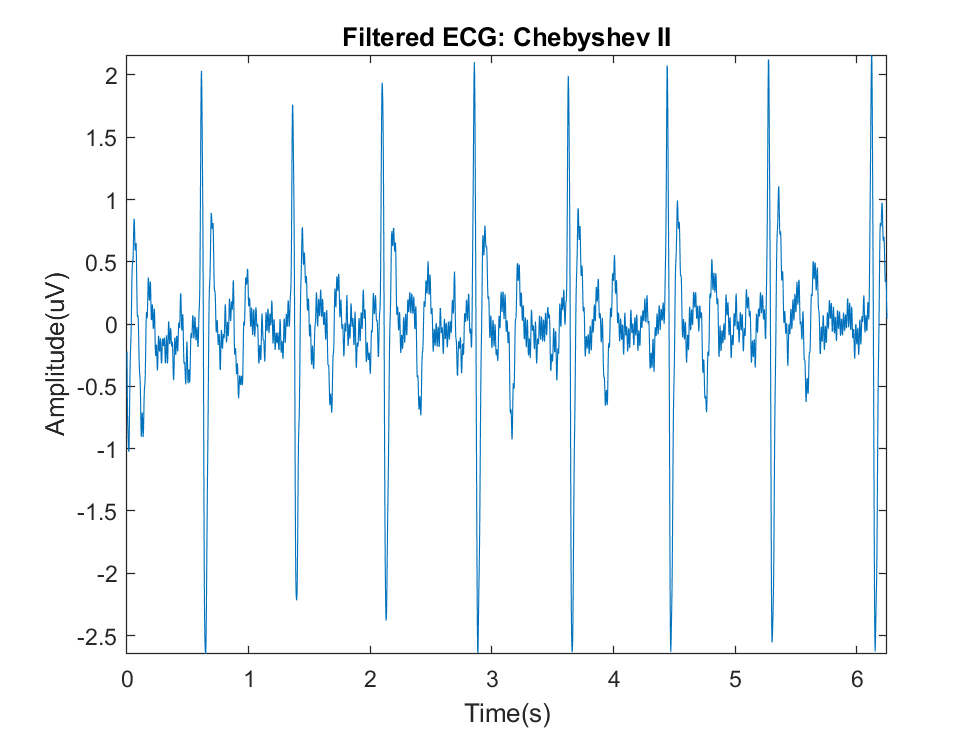

Fc = 4;
Wn = Fc/Fs;                                %Frecuencia normalizada
[num,den] = cheby2(3,50,Wn,'high');
Cheby2_Friday = filter(num,den,Friday);

Fc = 50;
Wn = Fc/Fs;                                %Frecuencia normalizada
[num,den] = cheby2(1,50,Wn,'low');
Cheby2_Friday = filter(num,den,Cheby2_Friday);

plot(T,Cheby2_Friday);
    axis tight;
    title('Filtered ECG: Chebyshev II');
    xlabel('Time(s)');
    ylabel('Amplitude(uV)');

## Tercer filtro: Wavelet Denoising

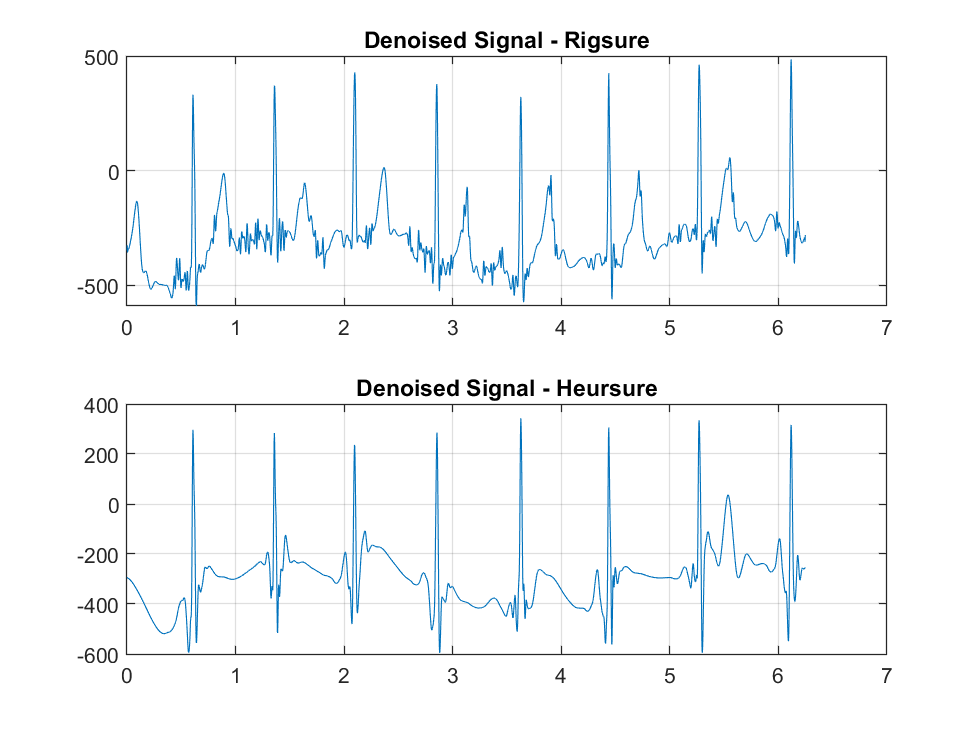

Level = 8;
Wavelet = 'sym8';
A = wden(Friday,'rigrsure','h','mln',Level,Wavelet);
B = wden(Friday,'heursure','h','mln',Level,Wavelet);
C = wden(Friday,'minimaxi','h','mln',Level,Wavelet);
D = wden(Friday,'sqtwolog','h','mln',Level,Wavelet);
subplot(2,1,1)
    plot(T,A)
        title('Denoised Signal - Rigsure')
        grid on
subplot(2,1,2)
    plot(T,B)
        title('Denoised Signal - Heursure')
        grid on

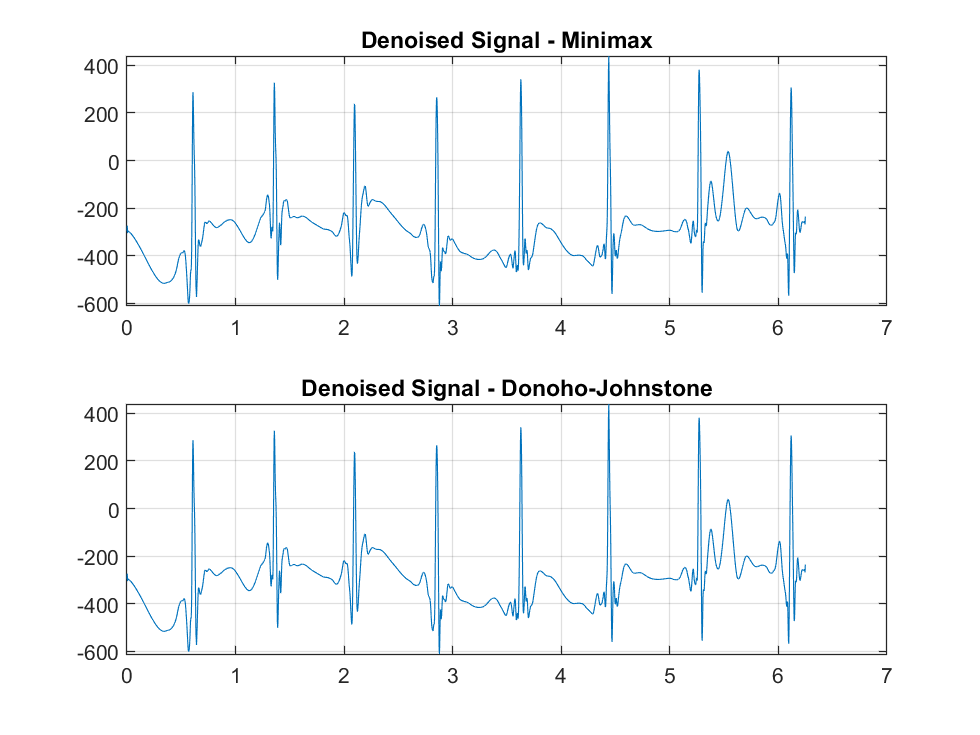

figure        
subplot(2,1,1)
    plot(T,C)
        title('Denoised Signal - Minimax')
        grid on
subplot(2,1,2)
    plot(T,C)
        title('Denoised Signal - Donoho-Johnstone')
        grid on         

## **Cuarto filtro: Transformada Rápida de Fourier (FFT)**

FFT_Friday = fft(Friday);
FFT_Friday = abs(Friday);